clear all, close all, clf
%bordsraket
v_yx = 21; %hastighet initialt
teta = deg2rad(81); % vinkel initialt
h=0.01;
F=1; %kraften
t1=0;
t2=0.08;
tend=4;



[z1,z2,z3,t_vals1,t_vals2,t_vals3,Error] = RocketMan(t1,t2,tend,h,1,v_yx,1,teta);

graderVektor=getdegvec(t_vals1,h,z1,teta);


ord1=Error(2,4);
ord2=Error(3,4);
delta11=Error(2,2);
delta12=Error(3,2);
delta21=Error(2,3);
delta22=Error(3,3);
ordningen ='≈16';
fprintf('Ordningnr1=%.4f\n',ord1);

Ordningnr1=16.0435


fprintf('Ordningnr2=%.4f\n',ord2);

Ordningnr2=16.1309


fprintf('felet första halvering i första delen=%.13f\n',delta11);%första delen är med F=1

felet första halvering i första delen=0.0000000000705


fprintf('felet andra halvering i första delen=%.13f\n',delta12);

felet andra halvering i första delen=0.0000000000044


fprintf('felet första halvering i andra delen=%.13f\n',delta21);%andra delen är med F=0

felet första halvering i andra delen=0.0000000000727


fprintf('felet andra halvering i andra delen=%.13f\n',delta22);

felet andra halvering i andra delen=0.0000000000045


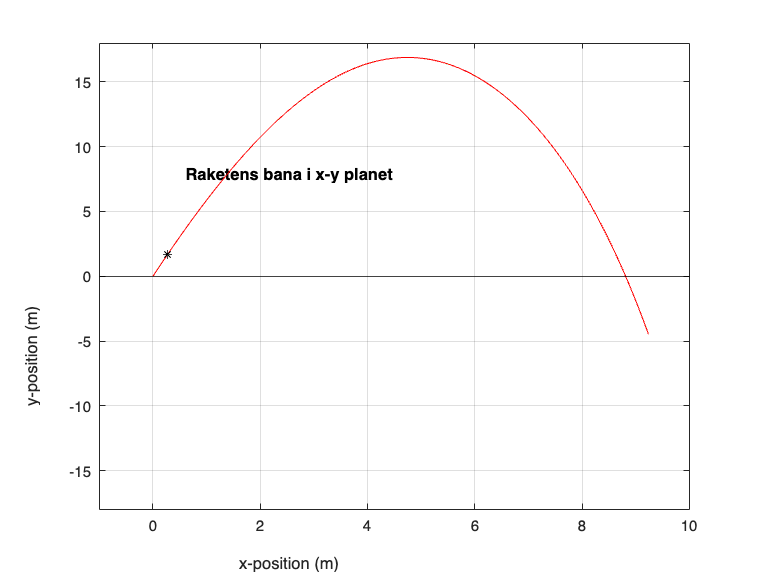




%------testa hitta t i högsta punkten
[t_for_ymax,iterationer1] = find_t_between(z3(4,:),t_vals3,1,0.0001,1e-6);

%----hitta t för nedslagsplatsen
[t_for_impact,iterationer2] = find_t_between(z3(2,:),t_vals3,1,0.0001,1e-6);

%------- hitta y_max
[~,itera] = find_vector_max(z3(2,:));
ymax=find_xy_val(z3(2,:),t_vals3,t_for_ymax,1,itera);

%---hitta nedslagsplatsen
[~,itera2] = find_vector_zero(z3(2,:));
x_impact=find_xy_val(z3(1,:),t_vals3,t_for_impact,1,itera2);

% Plotta lösningen
figure;
plot(z1(1,:), z1(2,:), 'b'); 
hold on
plot(z2(1,:), z2(2,:), 'g'); 
plot(z3(1,:), z3(2,:), 'r');
plot(z3(1,34), z3(2,34), '*-k');


xlim([-1,10])
ylim([-18,18]);
yline(0,'-k')
xlabel('x-position (m)'); 
ylabel('y-position (m)');
title('Raketens bana i x-y planet');
grid on;



%sekantmetoden i en funktion
f_g = @(x) exp(x)-sin(x)-2;%testfunktion
[rooooot,iter_v]= find_root_secant(f_g,1,1.4,1e-6);%test av sekant


